# Bayesian inference

We'll illustrate Bayesian inference with a very simple example. Suppose we want to estimate the mean of a sample of $n$ observations, $x_1, \ldots, x_n$ from a Gaussian distribution with unknown mean $\mu$ and known variance $\sigma^2$. Also suppose that we have some information about the distribution of the mean that we want to incorporate into the estimate. This information is expressed as the prior probability $p(\mu)$. In this example, we'll suppose that


$$p(\mu) = N(\mu | \mu_0, \sigma_0^2)$$


which says that we believe that $\mu$ follows a normal distribution centered at $\mu_0$ and with variance $\sigma_0^2$. The quantities $\mu_0$ and $\sigma^2_0$ are known.

Bayesian inference computes a posterior distribution $p(\mu|x_1,\ldots,x_n)$ using the likelihood function of the data, the prior probability, and Bayes' rule. After working through the algebra, we find a posterior distribution that has the form of a Gaussian,


$$p(\mu|x_1,\ldots,x_n) = N(\mu | \mu_n, \sigma_n^2)$$


where $\mu_n$ and $\sigma_n^2$ can be expressed in terms of the known quantities, $\sigma^2$, $\mu_0$, $\sigma_0^2$, and $x_1, \ldots, x_n$,  and are

                                                    
$$\mu_n = \frac{n \sigma_0^2}{n \sigma_0^2 + \sigma^2} \bar{x} + \frac{\sigma^2}{n \sigma_0^2 + \sigma^2} \mu_0$$


                                                    
$$\sigma_n^2 = \frac{\sigma^2}{n \sigma_0^2 + \sigma^2} \sigma_0^2$$


We'll now use this formulas to plot the prior and posterior distributions, giving some data.

The observations $x_1, \ldots, x_n$ are from a Gaussian distribution with unknown mean $\mu$ but known variance $\sigma^2$. Let this unknown mean be 1. Let the known variance $\sigma^2$ also be 1. We expect that the mean of the sample will be near this unknown mean of 1. The distribution of the mean should also be narrower for larger $n$. Note that in the code below, we will use standard deviations rather than variances.

mu = 1;
sigma = 1;

We'll randomly generate some data using this distribution. The number of observations is $n$.

n = 10;
x = randn(n,1)*sigma + mu;


For the known prior normal distribution, let's also pick some values for the mean and variance, which we can adjust for experimentation.

mu0    = 0.9;
sigma0 = 0.3;

Now we have everything to apply the formulas to compute the posterior distribution. The posterior is Gaussian, and we only need to compute its mean and variance.

denom = n*sigma0^2 + sigma^2;
mu_n = (n*sigma0^2/denom)*mean(x) + (sigma^2/denom)*mu0;
sigma_n = sqrt(1/denom)*sigma*sigma0;

Print some estimates of the mean. Notice how a good prior distribution can improve the estimate that is based on just the mean of the observations.

fprintf('Mean of observations: %f\n', mean(x));

Mean of observations: 1.253294


fprintf('Mean of prior:        %f\n', mu0)

Mean of prior:        0.900000


fprintf('Mean of posterior:    %f\n', mu_n);

Mean of posterior:    1.067350


Let's plot the prior distribution, the data, and the posterior distribution. First compute the range that we should plot for the distributions.

xxmin = min(mu0 - 3*sigma0, mu_n - 3*sigma_n);
xxmax = max(mu0 + 3*sigma0, mu_n + 3*sigma_n);
xx = linspace(xxmin, xxmax);

Now do the actual plotting.

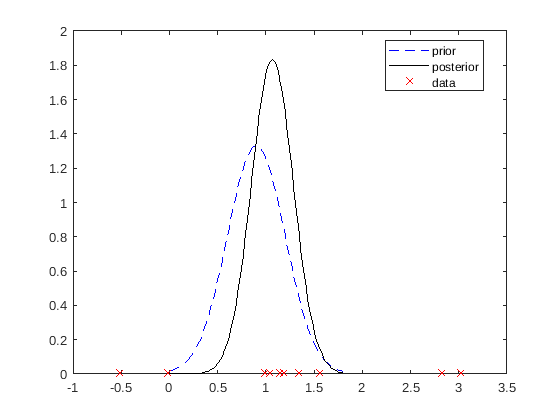

clf
plot(xx, normpdf(xx, mu0, sigma0),'b--'); % prior distribution
hold on
plot(xx, normpdf(xx, mu_n, sigma_n), 'k-'); % posterior distribution
plot(x,zeros(n,1),'rx');
legend('prior','posterior','data','location', 'best')

Notice here that the posterior distribution is always more narrow than the prior distribution.

To be clear, these are distributions for the mean, not the distribution of the observations. However, we expect that the estimate of the mean is close to the mean of the distribution of the observations, which is 1. The variance of these distributions indicate how certain we are about the location of the estimate, and should not be related to the variance of the distribution of the mean of samples of size $n$. The latter is known to be $\sigma^2/n$.

### Taking it further

Use the above code to investigate different scenarios. For example, what happens if the prior distribution has small variance but is wrong about the location of the mean?